# Summary of days (hour) by trial mean

clearvars -except kg

## Good kg idx

zx = 1;

%4:4 LD
ch1hourexp(zx).idx = [1 2 54];
    ch1hourexp(zx).hour = 4;
ch2hourexp(zx).idx = [1 2 55];
    ch2hourexp(zx).hour = 4;
    
    

%5:5 LD

    %zx = 2;
    zx = zx + 1;

ch1hourexp(zx).idx = [19 58 18]; %59 %18 = 19 different poweridx
    ch1hourexp(zx).hour = 5;
ch2hourexp(zx).idx = [19 96 18]; %59
    ch2hourexp(zx).hour = 5;

 %6:6 LD
 
    %zx = 3;
    zx = zx + 1;

ch1hourexp(zx).idx = [8 32 33]; %9
    ch1hourexp(zx).hour = 6;
ch2hourexp(zx).idx = [32 33];
    ch2hourexp(zx).hour = 6;

    %zx = 4;
    zx = zx + 1;

%8:8 LD
ch1hourexp(zx).idx = [27 25 26 35 36];
    ch1hourexp(zx).hour = 8;
ch2hourexp(zx).idx = [25 26 35 36];
    ch2hourexp(zx).hour = 8;

    %zx = 5;
    zx = zx + 1;

%10:10 LD
ch1hourexp(zx).idx= [6 7 60]; %61 outlier fish
    ch1hourexp(zx).hour = 10;
ch2hourexp(zx).idx = [6 7 60]; %61 outlier fish
    ch2hourexp(zx).hour = 10;

    %zx = 6;
    zx = zx + 1;

%12:12 LD
ch1hourexp(zx).idx = [12 14 16 17 22];
    ch1hourexp(zx).hour = 12;
ch2hourexp(zx).idx = [12 14 16 47 17 22];
    ch2hourexp(zx).hour = 12;

    %zx = 7;
    zx = zx + 1;

%13:13 LD
ch1hourexp(zx).idx = [31 28]; %29 - multimodal %30 bad data
    ch1hourexp(zx).hour = 13;
ch2hourexp(zx).idx = [28 31]; %29
    ch2hourexp(zx).hour = 13;

    %zx = 8;
    zx = zx + 1;

%20:20 LD
ch1hourexp(zx).idx = [37 38 40]; %39
    ch1hourexp(zx).hour = 20;
ch2hourexp(zx).idx = [37 38 40]; %39
    ch2hourexp(zx).hour = 20;

    %zx = 9;
    zx = zx + 1;

%24:24 LD
ch1hourexp(zx).idx = [56 11 10]; %57 
    ch1hourexp(zx).hour = 24;
ch2hourexp(zx).idx = [11 10 57]; %57
    ch2hourexp(zx).hour = 24;
    
    %zx = 10;
    zx = zx + 1;

%48:48 LD
ch1hourexp(zx).idx = [3 4 5 44 46];
    ch1hourexp(zx).hour = 48;
ch2hourexp(zx).idx = [3 4 5 44 48]; %44 45
    ch2hourexp(zx).hour = 48;
    
ReFs = 10;    

Resample rate for cubic spline estimate. Units in samples per hour

ReFs = 10;

## Day summaries by channel and light transition

Darkdays = dark to light

    light = 3

Lightdays = light to dark

    light = 4

#### Darkday channel 1

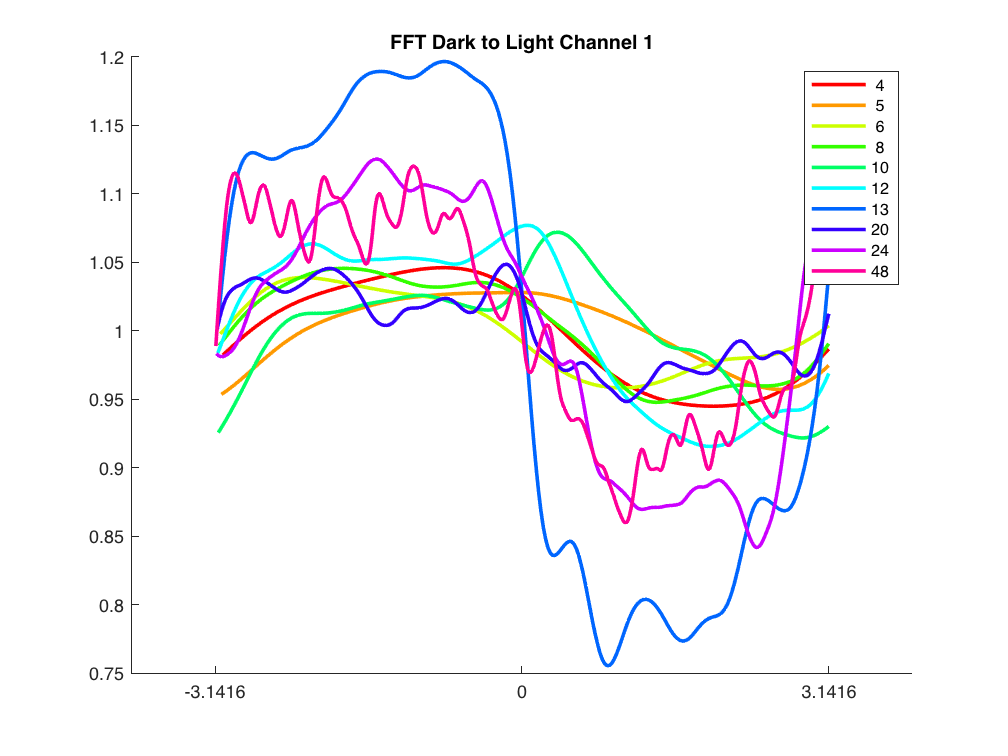

%channel 1 DarkDays
for k = 1:length(ch1hourexp)
    
    for kk = 1:length(ch1hourexp(k).idx)
         [dark1(k).h(kk).trial, dark1(k).h(kk).day] = KatiefftDayTrialDessembler(kg(ch1hourexp(k).idx(kk)), 1, ReFs, 3);
        
    end
    
    [dark1(k).hourtim, dark1(k).meanoftrialmeans, dark1(k).ld] = k_fftdaymeans(dark1(k).h);
    
end

clear ld; 
clear p;
%plot
figure(315); clf; title('FFT Dark to Light Channel 1'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
clrs = hsv(length(dark1));
%colororder(clrs);

    for j = 1:length(dark1)

      
        ld(j,:) = dark1(j).ld;
        crosshour = (2*pi) / (2 * dark1(j).ld);
        p(j) = plot((dark1(j).hourtim .* crosshour)-pi, dark1(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end

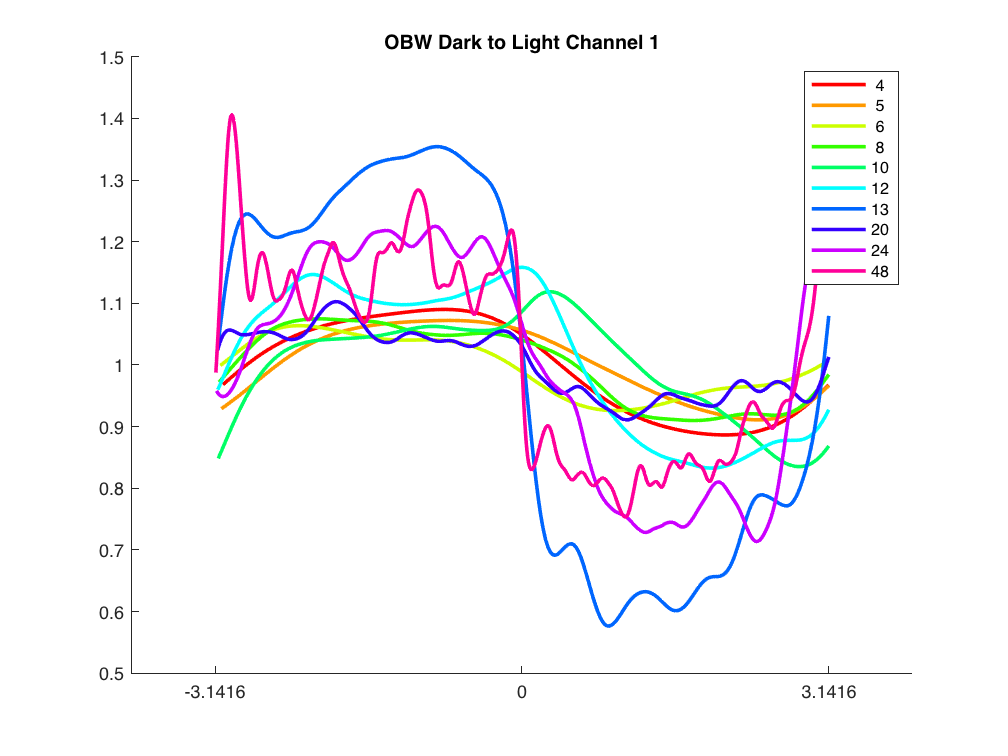

%channel 1 DarkDays
for k = 1:length(ch1hourexp)
    
    for kk = 1:length(ch1hourexp(k).idx)
         [dark1(k).h(kk).trial, dark1(k).h(kk).day] = KatieDayTrialDessembler(kg(ch1hourexp(k).idx(kk)), 1, ReFs);
        
    end
    
    [dark1(k).hourtim, dark1(k).meanoftrialmeans, dark1(k).ld] = k_daymeans(dark1(k).h);
    
end

clear ld; 
clear p;
%plot
figure(415); clf; title('OBW Dark to Light Channel 1'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
clrs = hsv(length(dark1));
%colororder(clrs);

    for j = 1:length(dark1)

      
        ld(j,:) = dark1(j).ld;
        crosshour = (2*pi) / (2 * dark1(j).ld);
        p(j) = plot((dark1(j).hourtim .* crosshour)-pi, dark1(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end

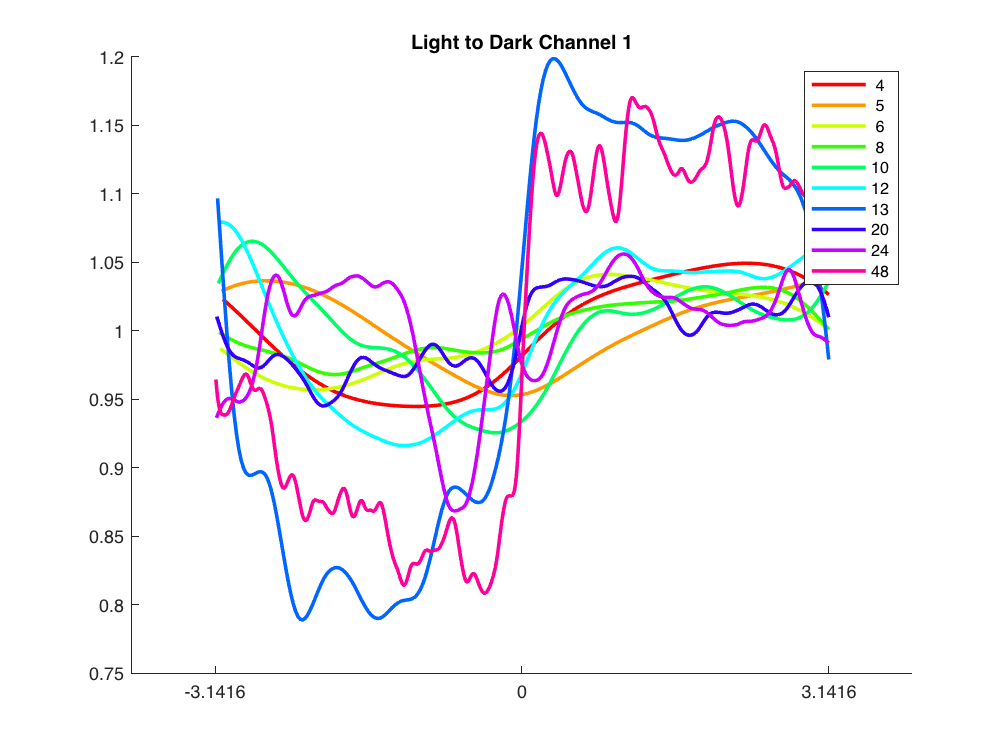

%channel 1 LightDays
for k = 1:length(ch1hourexp)
    
    for kk = 1:length(ch1hourexp(k).idx)
         [light1(k).h(kk).trial, light1(k).h(kk).day] = KatiefftDayTrialDessembler(kg(ch1hourexp(k).idx(kk)), 1, ReFs, 4);
        
    end
    
    [light1(k).hourtim, light1(k).meanoftrialmeans, light1(k).ld] = k_fftdaymeans(light1(k).h);
    
end
%plot
figure(314); clf; title('Light to Dark Channel 1'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
clear ld;
clrs = hsv(length(light1));
%colororder(clrs);

    for j = 1:length(light1)

      
        ld(j,:) = light1(j).ld;
        crosshour = (2*pi) / (2 * light1(j).ld);
        p(j) = plot((light1(j).hourtim .* crosshour)-pi, light1(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end

%channel 2 DarkDays
for k = 1:length(ch2hourexp)
    
    for kk = 1:length(ch2hourexp(k).idx)
         [dark2(k).h(kk).trial, dark2(k).h(kk).day] = KatiefftDayTrialDessembler(kg(ch2hourexp(k).idx(kk)), 2, ReFs, 3);
        
    end
    
    [dark2(k).hourtim, dark2(k).meanoftrialmeans, dark2(k).ld] = k_fftdaymeans(dark2(k).h);
    
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

Error in k_fftdaymeans (line 24)
        mday(jj,:) = zeros(1,length(in(j).trial(jj).tim));


%plot
figure(316); clf; title('Dark to Light Channel 2'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
clear ld;
clrs = hsv(length(dark2));
%colororder(clrs);

    for j = 1:length(dark2)

      
        ld(j,:) = dark2(j).ld;
        crosshour = (2*pi) / (2 * dark2(j).ld);
        p(j) = plot((dark2(j).hourtim .* crosshour)-pi, dark2(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end


%channel 2 LightDays
for k = 1:length(ch2hourexp)
    
    for kk = 1:length(ch2hourexp(k).idx)
         [light2(k).h(kk).trial, light2(k).h(kk).day] = KatiefftDayTrialDessembler(kg(ch2hourexp(k).idx(kk)), 2, ReFs, 4);
        
    end
    
    [light2(k).hourtim, light2(k).meanoftrialmeans, light2(k).ld] = k_fftdaymeans(light2(k).h);
    
end

%plot
figure(317); clf; title('Light to Dark Channel 2'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
clear ld;
clrs = hsv(length(light2));
%colororder(clrs);

    for j = 1:length(light2)

      
        ld(j,:) = light2(j).ld;
        crosshour = (2*pi) / (2 * light2(j).ld);
        p(j) = plot((light2(j).hourtim .* crosshour)-pi, light2(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end


 plot([0 0], ylim, 'k-');